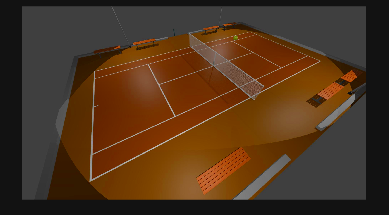

imagePath = "captures\rightImg_1.jpeg";
% Read the image from the specified path
img = imread(imagePath);
imshow(img);

yCbCr = rgb2ycbcr(img);
y = yCbCr(:, :, 1);
Cr = yCbCr(:, :, 2);
Cb = yCbCr(:, :, 3);

imshow(y)
imshow(Cr)
imshow(Cb)

hsvImg = rgb2hsv(img);
H = hsvImg(:, :, 1);
S = hsvImg(:, :, 2);
V = hsvImg(:, :, 3);

imshow(H)
imshow(S)
imshow(V)

hsvImg(:, :, 2) = S * 1.5; % Increase saturation by 50%
imshow(S)

satImg = hsv2rgb(hsvImg);
imshow(satImg)


redMask = (Cr > 90);
% Create a binary mask for red regions
redRegions = yCbCr(:, :, 1) > 150 & redMask;